In this file, we derive the Q-matrix of the Markov reward process corresponding to the multiprocessor system described in Smith, R., et al. (1988). "Performability analysis: measures, an algorithm, and a case study." IEEE Transactions on Computers 37(4): 406-417.

## Description of the case study

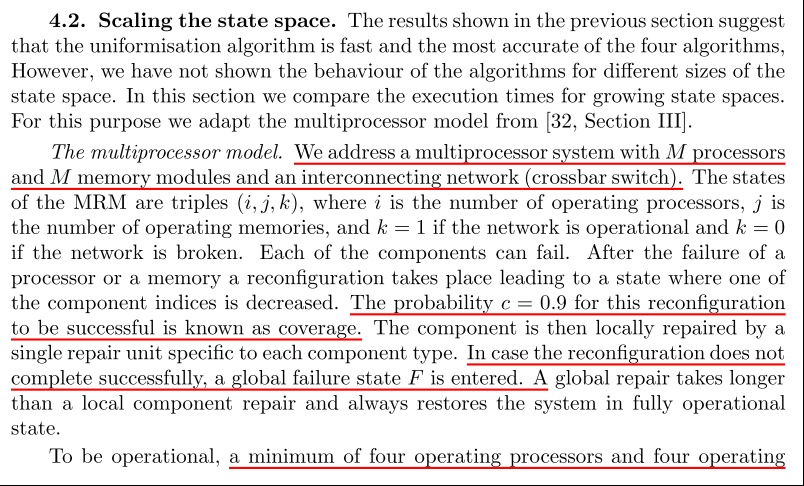

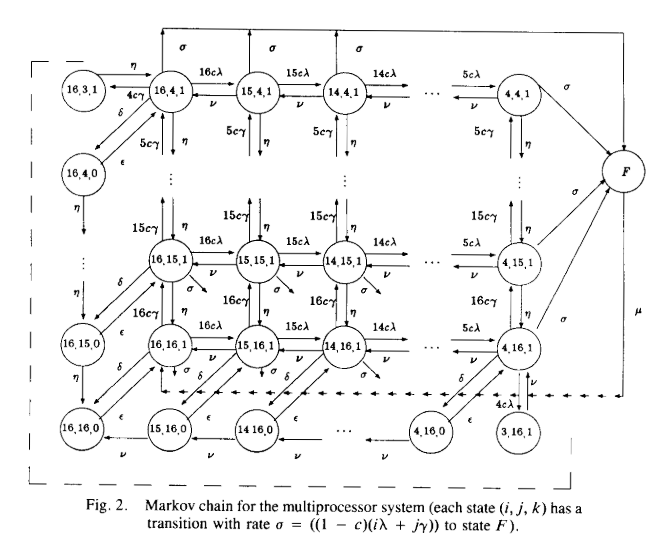

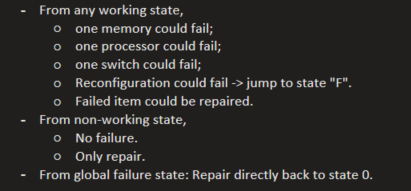

## Indexes of states

Let $(i,j,k),0\le i\le m, 0\le j \le m, k = 0,1.$ represent the number of working processors, memories and switches, respectively. Altogether, we have $(m-2)^2+(m-3)^3$ states:

- $k=1$ (switch is on), $i=3,4,\cdots,m, j = 3,4,\cdots,m,$ except for the state $(3,3,1).$ The state $(3,3,1)$ has to be excluded because, it can only be transfered from $(3,4,1) $ or $(4,3,1)$. But these two states are already failure states, as processors or memories already fell below $4.$ So the transition is not possible (no failures in the down state). So alltogether we have $(m-2)^2-1$ for this condition.

- $k=0$ (switch is off), $i=4,\cdots,m, j = 4,\cdots,m,$ these are the failure states. Alltogether we have $(n-3)^2$ states.

- We have an additional state "F" for the global failure state.

We have a subfunction to_state_idx.m which translates the component state vector $(i,j,k)$ into its system state index. Here we run a test by considering all the possible component state combination to check if the resulted indexes are in $[1,(m-2)^2+(m-3)^2-1]$.

clear; clc;
% Define parameters.
m = 16; % Number of components.
state_idx = zeros(1,(m-2)^2+(m-3)^2-1); % Intial values.
% Do a loop to fill the elements in state_idx.
counter = 1;
% First consider k == 1.
k = 1;
for i = m:-1:4
    for j = m:-1:4
        state_idx(counter) = to_state_idx(i,j,k,m);
        counter = counter + 1;
    end
end
i = 3;
for j = m:-1:4
    state_idx(counter) = to_state_idx(i,j,k,m);
    counter = counter + 1;
end
j = 3;
for i = m:-1:4
    state_idx(counter) = to_state_idx(i,j,k,m);
    counter = counter + 1;
end
% Then, k == 0.
k = 0;
for i = m:-1:4
    for j = m:-1:4
        state_idx(counter) = to_state_idx(i,j,k,m);
        counter = counter + 1;
    end
end
% Display the results.
state_idx = sort(state_idx);
disp(state_idx);

  Columns 1 through 16

     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16

  Columns 17 through 32

    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32

  Columns 33 through 48

    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48

  Columns 49 through 64

    49    50    51    52    53    54    55    56    57    58    59    60    61    62    63    64

  Columns 65 through 80

    65    66    67    68    69    70    71    72    73    74    75    76    77    78    79    80

  Columns 81 through 96

    81    82    83    84    85    86    87    88    89    90    91    92    93    94    95    96

  Columns 97 through 112

    97    98    99   100   101   102   103   104   105   106   107   108   109   110   111   112

  Columns 113 through 128

   113   114   115   116   117   118   119   120   121   122   123   124   125   126   127   128

  Columns 129 

## Derive the Q-matrix

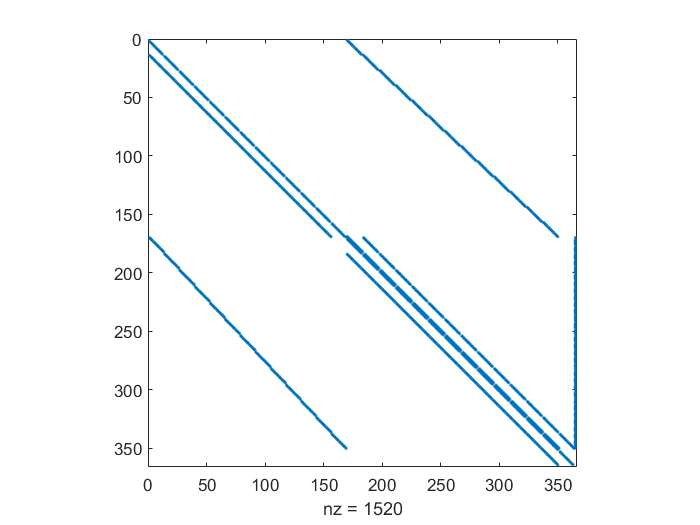

clear; clc;
% Define failure rates and repair rates.
para.lambda = 6.89e-5; % Failure rate for the processor.
para.gamma = 2.2241e-4; % Failure rate for the memory.
para.delta = 2.2024e-4; % Failure rate for the switch.
para.nu = 2; % Local repair rate for the processor.
para.eta = 1; % Local repair rate for the memory.
para.epsilon = .5; % Local repair rate for the switch.
para.mu = .2; % Global repair rate.
para.c = .9; % Coverage probability.
m = 16;
x_0.i = m;
x_0.j = m;
x_0.k = 1;

[Q_sp, Q_full, r, pi_0] = Q_matrix(m, para, x_0);
spy(Q_sp);

## Test sparse matrix or full matrix is faster for the numerical integration.

Use the same setting, but use full matrix and sparse matrix representation for Q. Check the running time.

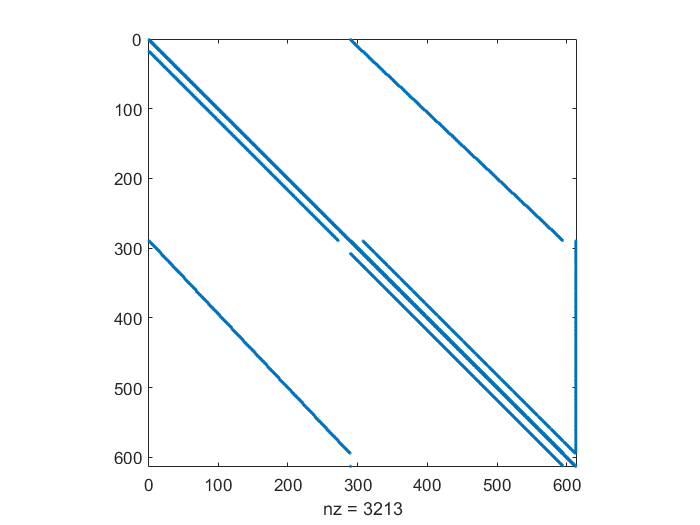

clear; clc;
% Define failure rates and repair rates.
para.lambda = 6.89e-2; % Failure rate for the processor.
para.gamma = 2.2241e-1; % Failure rate for the memory.
para.delta = 2.2024e-1; % Failure rate for the switch.
para.nu = 2; % Local repair rate for the processor.
para.eta = 1; % Local repair rate for the memory.
para.epsilon = .5; % Local repair rate for the switch.
para.mu = .2; % Global repair rate.
para.c = .9; % Coverage probability.
m = 20;
x_0.i = m;
x_0.j = m;
x_0.k = 1;

[Q_sp, Q_full, r, pi_0] = Q_matrix(m, para, x_0);
spy(Q_sp);

whos Q_sp Q_full

  Name          Size               Bytes  Class     Attributes

  Q_full      613x613            3006152  double              
  Q_sp        613x613              56320  double    sparse    



addpath('../')
%% Start a test to calculate the CDF of AR.
T_max = 10;
x_max = 10;
% Scale the r and x_max to make them integral.
r = floor(r*10);
x_max = x_max*10;
% Defining the structure para
para_1.S = 1:(m-2)^2+(m-3)^2;
para_1.pi = pi_0;
para_1.Q = Q_sp;
para_1.r = r;
Delta = .02;
tic;
accumulated_reward_numit_ext_markov(T_max,x_max,Delta,para_1);
et_sp = toc

et_sp = 22.3049

para_1.Q = Q_full;
tic;
accumulated_reward_numit_ext_markov(T_max,x_max,Delta,para_1);
et_full = toc

et_full = 21.5003

So the full matrix representation is slightly quicker, but not very significant. Another interesting observation is that, the truncation errors in Q: the row sum does not strictly equals to 0:

sum(Q_full,2)